% ESA Dynamics HW 3 - Spring Pendulum
% Chris Allum 4.14.21
clc
clearvars

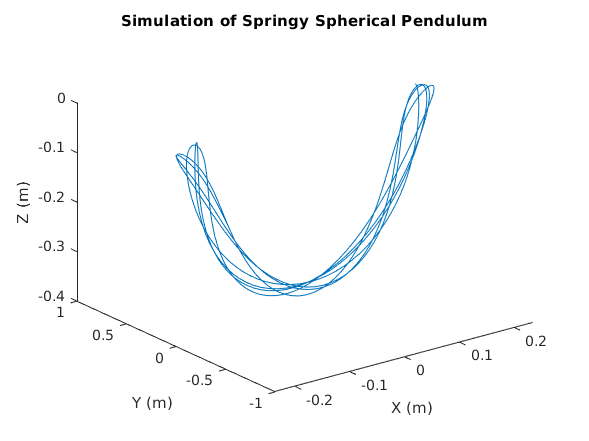

% initial position
r0 = .2;
theta0 = 0;
phi0 = pi/2;

% initial velocity
dr0 = .1;
dtheta0 = 0;
dphi0 = 0;

% pack initial conditions into column vector
init = [r0 dr0 theta0 dtheta0 phi0 dphi0]';

% run simulation
[t,p] = simulation(init);

% plot spring pendulum simulation
plot3D(t,p)

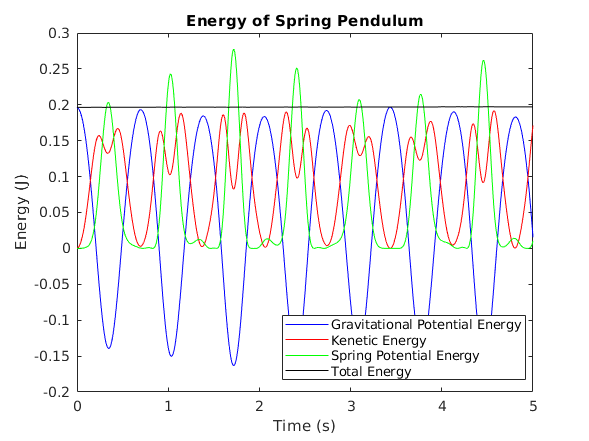


% energy calculations
plotEnergy(t,p)

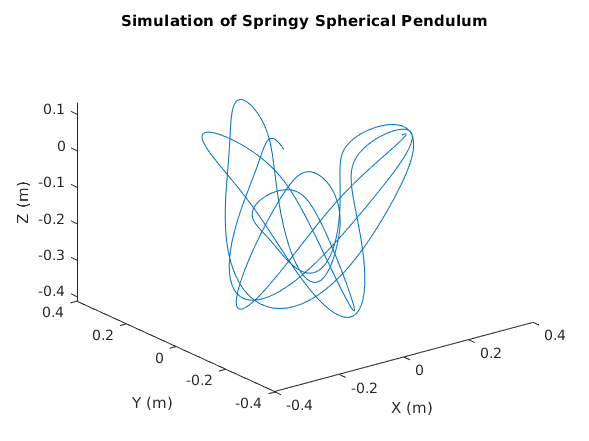

% initial position
r0 = .3;
theta0 = 0;
phi0 = pi/2;

% initial velocity
dr0 = 1;
dtheta0 = 1;
dphi0 = 0;

% pack initial conditions into column vector
init = [r0 dr0 theta0 dtheta0 phi0 dphi0]';

% run simulation
[t,p] = simulation(init);

% plot spring pendulum simulation
plot3D(t,p)

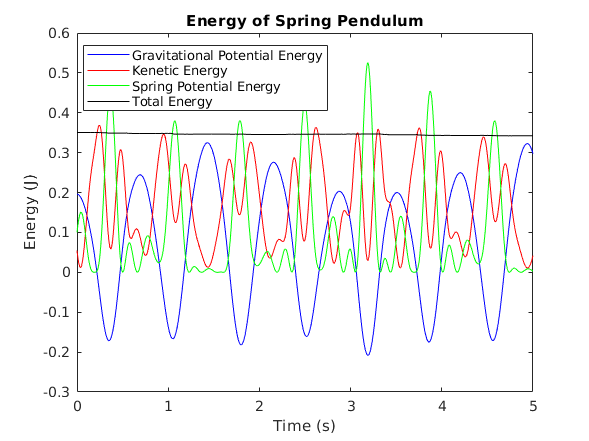


% energy calculations
plotEnergy(t,p)

function [t,p] = simulation(init)
    
    % time span
    tspan = [0:.01:5];
    
    % simulation params, used in ODE funcs
    g = 9.8;
    k = 20;
    l = .2;
    m = .1;
    
    % use ode45 and stop at event
    options = odeset('Events', @eventFcn);
    [t,p] = ode45(@f,tspan,init);
    
    % define ODEs
    function dpdt = f(~,p)
        
        dr = p(2);
        ddr = (k/m)*(l-p(1))-g*cos(p(5))+p(1)*p(4)^2*sin(p(5))^2+p(1)*p(6)^2;
        dtheta = p(4);
        ddtheta = (-2*p(1)*p(4)*p(6)*cos(p(5))-2*p(2)*p(4)*sin(p(5)))/(p(1)*sin(p(5)));
        dphi = p(6);
        ddphi = (g*sin(p(5))+p(1)*p(4)^2*sin(p(5))*cos(p(5))-2*p(2)*p(6))/p(1);

        % pack ODEs into column vector
        dpdt = [dr ddr dtheta ddtheta dphi ddphi]';
    end
    
    function [position,isterminal,direction] = eventFcn(~,p)
        position = p(5); % The value that we want to be zero
        isterminal = 1;  % Halt integration 
        direction = 0;   % The zero can be approached from either direction
    end

end

function plot3D(t,p)
    % grab polar values from p matrix
    r = p(:,1);
    theta = p(:,3);
    phi = p(:,5);
    
    % convert to cartesian
    x = r.*sin(phi).*cos(theta);
    y = r.*sin(phi).*sin(theta);
    z = r.*cos(phi);
    
    % plot and label figure
    figure
    plot3(x,y,z)
    title("Simulation of Springy Spherical Pendulum")
    xlabel("X (m)")
    ylabel("Y (m)")
    zlabel('Z (m)')
end

function plotEnergy(t,p)
    % system params
    g = 9.8;
    k = 20;
    l = .2;
    m = .1;  
    
    % grab polar values from p matrix
    r = p(:,1);
    dr = p(:,2);
    theta = p(:,3);
    dtheta = p(:,4);
    phi = p(:,5);
    dphi = p(:,6);
    
    % convert to cartesian
    z = r.*cos(phi)+l;
    
    % energy calcs
    V = vecnorm([dr r.*dtheta.*sin(phi) r.*dphi]')';
    
    PE = m*g.*z;
    KE = 0.5*m.*V.^2;
    SE = 0.5*k.*(l-r).^2;
    
    figure
    plot(t,PE,"b"), hold on
    plot(t,KE,'r')
    plot(t,SE,"g")
    plot(t,PE+SE+KE,"k")
    title("Energy of Spring Pendulum")
    xlabel("Time (s)")
    ylabel("Energy (J)")
    legend(["Gravitational Potential Energy","Kenetic Energy","Spring Potential Energy","Total Energy"],"Location","best")
end